# Cardiac 0701 segmentation

% Stardist
merge_dim = 7;
run_id = strcat("stardist_", num2str(merge_dim))

run_id = "stardist_7"


basePath = 'E:\Cardiac_0701\output\layer_seg\';
outputPath = 'E:\Cardiac_0701\output\merged_seg\';


dirs = dir(strcat(basePath, 'position*'));
dirs = struct2table(dirs);
dirs = natsort(dirs.name)

dirs = 27×1 cell array
    {'position1' }
    {'position2' }
    {'position3' }
    {'position4' }
    {'position5' }
    {'position6' }
    {'position7' }
    {'position8' }
    {'position9' }
    {'position10'}
    {'position11'}
    {'position12'}
    {'position13'}
    {'position14'}
    {'position15'}
    {'position16'}
    {'position17'}
    {'position18'}
    {'position19'}
    {'position20'}
    {'position21'}
    {'position22'}
    {'position23'}
    {'position24'}
    {'position25'}
    {'position26'}
    {'position27'}


% dirs = dirs(1:30) % TEST USAGE

se = strel('disk', 2);

Ncells = 0;
Volumes = [];

for p=1:numel(dirs)
    tic
    curr_dir = dirs{p};
    fprintf('Loading %s...', curr_dir);
    curr_files = dir(fullfile(basePath, curr_dir, 'stardist_output', '*.tif'));
    curr_files = struct2table(curr_files);
    curr_files = natsort(curr_files.name);
    seg_mask = uint16(zeros(1024, 1024, numel(curr_files)));
    for c=1:numel(curr_files)
        %curr_files{c}
        curr_path = fullfile(basePath, curr_dir, 'stardist_output', curr_files{c});
        curr_img = imread(curr_path);
        input_img = imdilate(curr_img, se);
        bmask = boundarymask(input_img);
%         input_img = label2rgb(input_img);
%         input_img = imcomplement(input_img);
%         input_img = rgb2gray(input_img);
        base_bw = imbinarize(input_img,0);
        %base_bw = imfill(base_bw, 'holes');
        bmask = imcomplement(bmask);
        out_bw = base_bw .* bmask;
        out_bw = bwareaopen(out_bw, 200);
%         figure
%         imshow(out_bw)
        seg_mask(:,:,c)=out_bw;
      
    end
    

    % compute center stack
    seg_bw = imbinarize(seg_mask);
    center_stack = zeros(size(seg_bw));

    for z=1:size(seg_bw,3)
        curr_slice = seg_bw(:,:,z);
        curr_centroid = regionprops(curr_slice, 'Centroid');
        curr_centroid = struct2table(curr_centroid);
        curr_centroid = int16(curr_centroid.Centroid);
       
        curr_center = get_spot_img(curr_slice, curr_centroid, [merge_dim merge_dim]); % adjust merge level
        center_stack(:,:,z) = curr_center;
    end
    
    center_stack = imbinarize(center_stack);
    
    % compute adjusted label stack
    label_stack = bwlabeln(center_stack, 6);
    
    curr_cells = numel(unique(label_stack)) - 1;
    Ncells = Ncells + curr_cells;
    fprintf(sprintf('Number of cells: %d', curr_cells));
    
    output_img = zeros(size(center_stack));
    
    for z=1:size(center_stack,3)
        curr_seg = seg_bw(:,:,z);
        curr_center = label_stack(:,:,z);
        curr_slice = output_img(:,:,z);
        
        curr_stat = regionprops(curr_seg, 'PixelIdxList');
        for i=1:numel(curr_stat)
            curr_cc = curr_stat(i).PixelIdxList;
            curr_label = unique(curr_center(curr_cc));
            if numel(curr_label) == 1
                curr_slice(curr_cc) = curr_label;
            else
                curr_label = curr_label(curr_label~=0);
                curr_slice(curr_cc) = curr_label(1);
            end
        end
        output_img(:,:,z) = curr_slice;
    end
    
    curr_volume = regionprops3(output_img, "Volume");
    Volumes = [Volumes; curr_volume.Volume]; 
    
    curr_out_dir = fullfile(outputPath, run_id, curr_dir);
    if ~exist(curr_out_dir, 'dir')
        mkdir(curr_out_dir);
    end
    
    label_fname = fullfile(curr_out_dir, 'label_img.tif');
    if exist(label_fname, 'file') == 2
        delete(label_fname);
    end
    for z=1:size(output_img,3)        
        imwrite(uint16(output_img(:,:,z)), label_fname, 'writemode', 'append');        
    end
    
    seg_fname = fullfile(curr_out_dir, 'seg_img.tif');
    if exist(seg_fname, 'file') == 2
        delete(seg_fname);
    end
    for z=1:size(seg_mask,3)        
        imwrite(uint16(seg_mask(:,:,z)), seg_fname, 'writemode', 'append');        
    end
    
    fprintf(sprintf('[time = %.2f s]\n', toc));
end

Loading position1...

Number of cells: 1036

[time = 7.11 s]


Loading position2...

Number of cells: 847

[time = 6.77 s]


Loading position3...

Number of cells: 1240

[time = 8.03 s]


Loading position4...

Number of cells: 897

[time = 6.96 s]


Loading position5...

Number of cells: 1061

[time = 7.21 s]


Loading position6...

Number of cells: 1103

[time = 7.54 s]


Loading position7...

Number of cells: 1302

[time = 7.85 s]


Loading position8...

Number of cells: 1213

[time = 8.20 s]


Loading position9...

Number of cells: 1493

[time = 8.33 s]


Loading position10...

Number of cells: 892

[time = 6.84 s]


Loading position11...

Number of cells: 1007

[time = 7.80 s]


Loading position12...

Number of cells: 700

[time = 6.47 s]


Loading position13...

Number of cells: 703

[time = 6.48 s]


Loading position14...

Number of cells: 622

[time = 6.05 s]


Loading position15...

Number of cells: 643

[time = 6.21 s]


Loading position16...

Number of cells: 1337

[time = 8.52 s]


Loading position17...

Number of cells: 994

[time = 7.68 s]


Loading position18...

Number of cells: 1266

[time = 8.30 s]


Loading position19...

Number of cells: 1943

[time = 8.28 s]


Loading position20...

Number of cells: 1569

[time = 7.89 s]


Loading position21...

Number of cells: 2421

[time = 8.97 s]


Loading position22...

Number of cells: 1960

[time = 8.95 s]


Loading position23...

Number of cells: 1659

[time = 8.15 s]


Loading position24...

Number of cells: 1682

[time = 7.98 s]


Loading position25...

Number of cells: 1711

[time = 8.35 s]


Loading position26...

Number of cells: 1544

[time = 7.51 s]


Loading position27...

Number of cells: 1780

[time = 8.76 s]


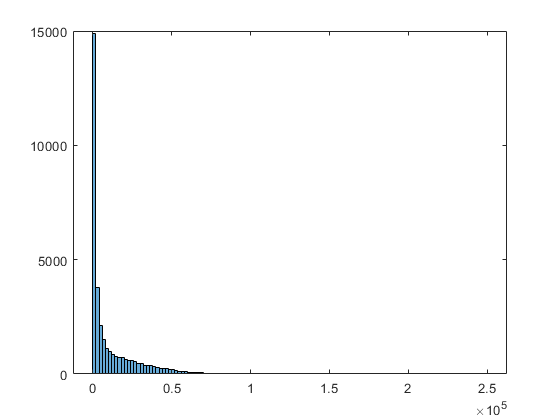


figure
histogram(Volumes)

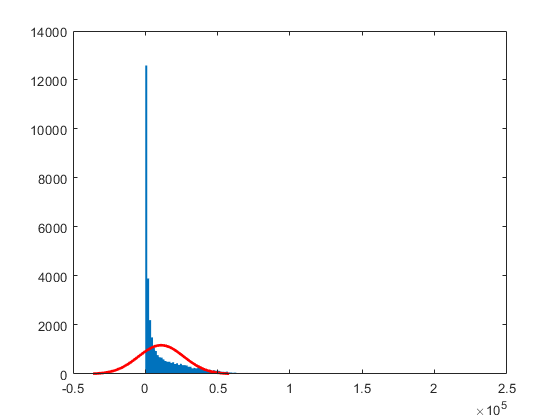


figure
histfit(Volumes)


fprintf(sprintf('Number of cells total: %d\n', Ncells));

Number of cells total: 34625


stat = [mean(Volumes), median(Volumes), std(Volumes), range(Volumes)];
fprintf(sprintf(['Mean: %.2f\n' ...
    'Median: %.2f\n'...
    'Std: %.2f\n'...
    'Range: %.2f'], stat));

Mean: 10928.68
Median: 3081.00
Std: 15676.86
Range: 248997.00